# ***CHW2 DSP***

## ***Dr.Shamsollahi***

## ***MohammadParsa Dini 400101204***

***Problem 1:***

***Part 1.1:***

In this section we assume we have a transfer function $H\left(z\right)=\frac{b_0 +b_1 z+\ldotp \ldotp \ldotp +b_k z^k }{a_{0\;} +a_1 z+\ldotp \ldotp \ldotp +a_{n\;} z^n }$, and we are given coefficients $a_{i\;} ,b_i$.

Firstly, we will compute the roots and poles of it, and then we will assign those of which to $H_{min} (z)$ that they have a norm less than one $|z|<1$.

 Hence, the other roots and poles will be asssigned to $H_{ap} (z)$ and for roots $1-{\textrm{az}}^{-1}$and poles $\frac{1}{1-{\textrm{az}}^{-1} }$ we will multiply terms such as $\frac{1}{z^{-1} -a^* }\;\;$

(or equivalently $\frac{1}{1-a^{*\;} z}$)or $z^{-1} -a^*$(or  equivalently$1-a^{*\;} z$) to the the present $H_{min} (z)$, $H_{ap} (z)$ if needs be in order to keep the DC gain constant.

In the given example we have $H\left(z\right)=\frac{1-2z^{-1} }{1-\frac{1}{4}z^{-1} }=\frac{z-2}{z-\frac{1}{4}}\;$, therefore

 $H_{\textrm{ap}\;} \left(z\right)=\frac{z-2}{1-2^* z}\times \frac{1-\frac{1^* }{4}z}{z-\frac{1}{4}}$and also 

$H_{\min } \left(z\right)=$$\frac{1-2^* z}{1-\frac{1^* }{4}z}$.

clear; close all; clc;
Ts = 0.01;
H_min = tf([1],[1],Ts);
H_ap = tf([1],[1],Ts);
z = tf('z');
%H = (1- 2*z^-1)/(1 - (1/4)*z^-1)
H = (z-2)/(z-1/4)

H =
 
   z - 2
  --------
  z - 0.25
 
Sample time: unspecified
Discrete-time transfer function.



zeros_tf = zero(H)

zeros_tf = 2

poles_tf = zero(1/H)

poles_tf = 0.2500

[zeros,poles] = remove_redundancy(zeros_tf,poles_tf)

zeros = 2

poles = 0.2500

Unfortunately, when matlab wanted to reformat the trasnfer function $H(z)$ by writing it in terms of $z^i , i \geq 0$, Matlab added a redundant zero pole and a zero root, which we handled it using `remove_redundancy(.,.)` fucntion which will also handle repetitive roots and poles as well.

[poles_lt1, poles_get1] = separator(transpose(poles))

poles_lt1 = 0.2500


poles_get1 =

     []



[roots_lt1, roots_get1] = separator(transpose(zeros))


roots_lt1 =

     []



roots_get1 = 2

% ----------------------------------------------------------
for p = poles_lt1
H_min = H_min / (z - p);
end
for r = roots_lt1
H_min = H_min * (z - r);
end
for p = poles_get1
H_ap = H_ap / (z - p);
H_ap = H_ap * (1-conj(p)*z);
H_min = H_min / (1-conj(p)*z);
end
for r = roots_get1
H_ap = H_ap * (z - r);
H_ap = H_ap / (1-conj(r)*z);
H_min = H_min * (1-conj(r)*z);
end
H_min

H_min =
 
  -2 z + 1
  --------
  z - 0.25
 
Sample time: 0.01 seconds
Discrete-time transfer function.



H_ap

H_ap =
 
  -z + 2
  -------
  2 z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



And as you can see, our function's output is valid and true since $H_{min}(z)$ consists of roots and poles of norm less than one, meanwhile the gain of $H_{ap} (z)$ is one. However, for the sake of conservation, we can remove the redundancies of output transfer functions.

So in the coming section, we will test our function:

***Part 1.2.1:***

Ts = 0.01;
num = [1 -2];
den = [1 -1/4];
z = tf('z',Ts);
G = (1- 2*z^-1)/(1 - (1/4)*z^-1)

G =
 
   z^2 - 2 z
  ------------
  z^2 - 0.25 z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



H_tf = tf(num, den, Ts)

H_tf =
 
   z - 2
  --------
  z - 0.25
 
Sample time: 0.01 seconds
Discrete-time transfer function.



[H_min, H_ap] = get_Hmin_Hap(num, den, Ts)

H_min =
 
  -2 z + 1
  --------
  z - 0.25
 
Sample time: 0.01 seconds
Discrete-time transfer function.


H_ap =
 
  -z + 2
  -------
  2 z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



[numm, denn] = tfdata(G, 'v');
[G_min, G_ap] = get_Hmin_Hap(numm, denn, Ts)

G_min =
 
  -2 z + 1
  --------
  z - 0.25
 
Sample time: 0.01 seconds
Discrete-time transfer function.


G_ap =
 
  -z + 2
  -------
  2 z - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



 So our function has passed the test of time! As you can see the output if iur function aligns with what we have shown earlier for 

H_ap and H_min. Eventually, we will plot the bode diagram and 

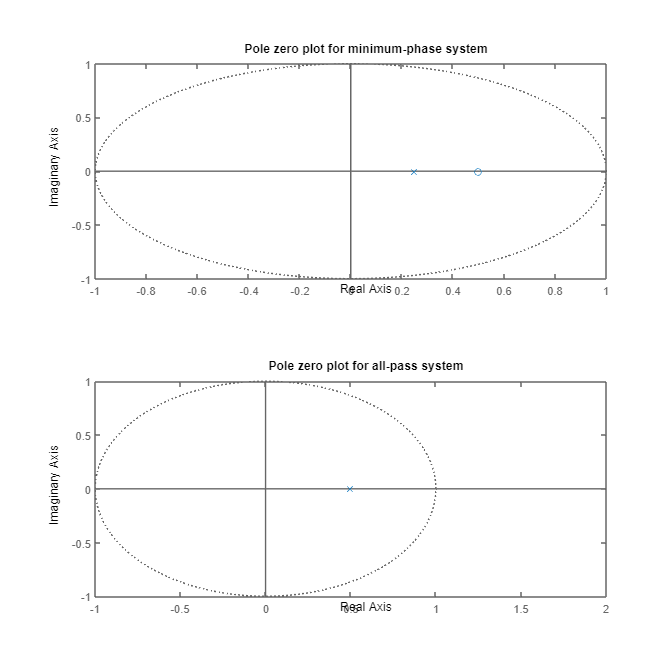


fig1 = figure(Position=[10,10,1000,1000]);
subplot(2,1,1)
pzplot(G_min)
title('Pole zero plot for minimum-phase system')
subplot(2,1,2)
pzplot(G_ap)
title('Pole zero plot for all-pass system')

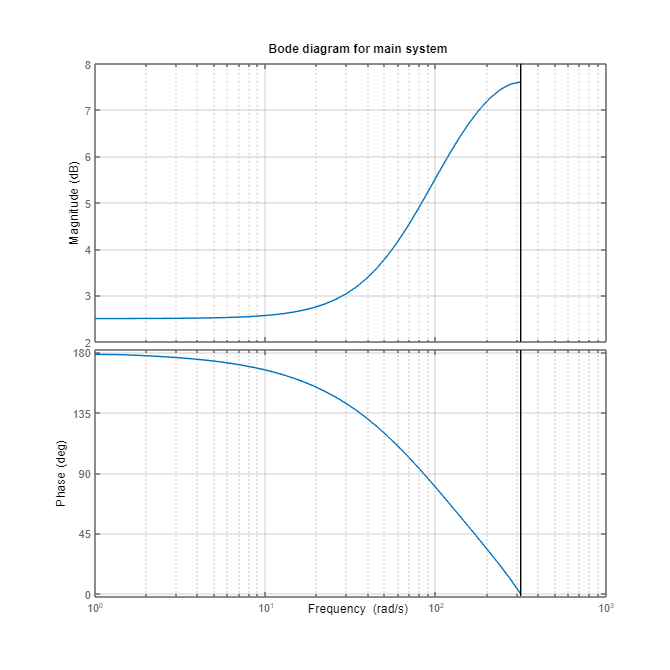


fig2 = figure(Position=[10,10,1000,1000]);
bode(G);
title('Bode diagram for main system')
grid on

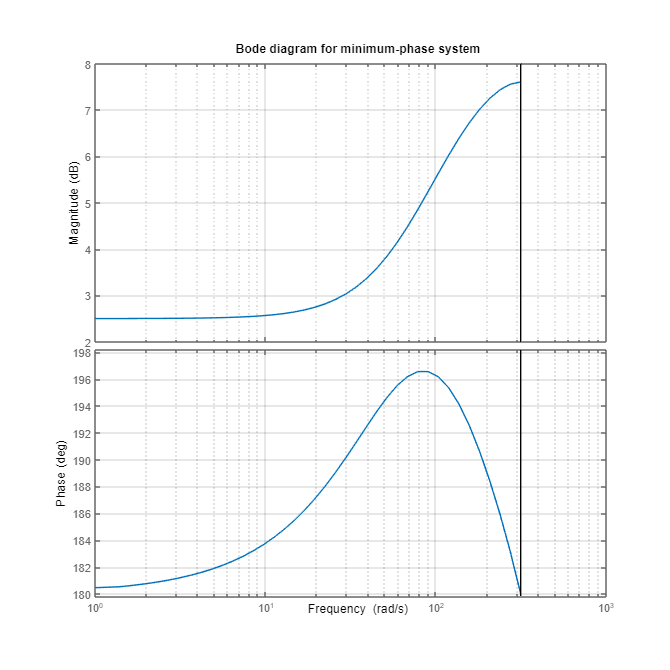


fig3 = figure(Position=[10,10,1000,1000]);
bode(G_min);
title('Bode diagram for minimum-phase system')
grid on

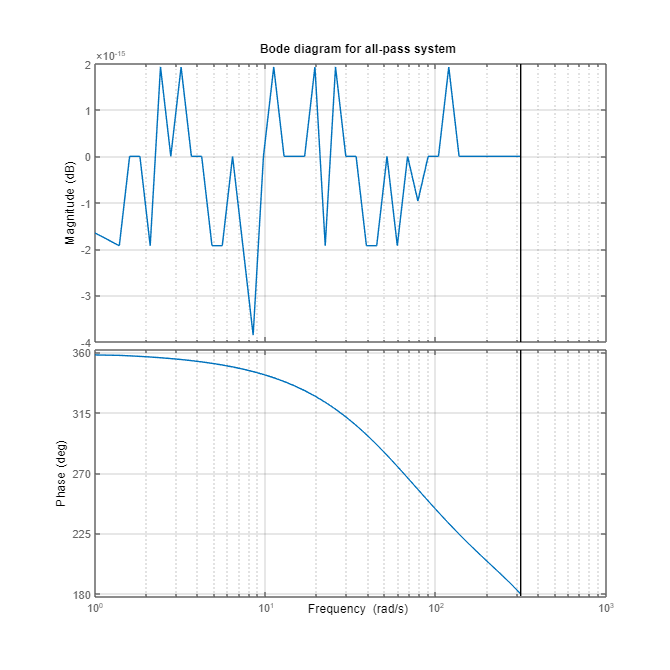


fig4 = figure(Position=[10,10,1000,1000]);
bode(G_ap);
title('Bode diagram for all-pass system')
grid on

It is worth mentioning that we developed annother function in order to get H_mini and H_ap which has the exact same poles and zeros, but it does n't have any problem with pllotting. As you see, there is something wrong with them. But the other method which we applied, confirmed the posistion of our oles and roots, but it was truen on the frequency response of the systems.

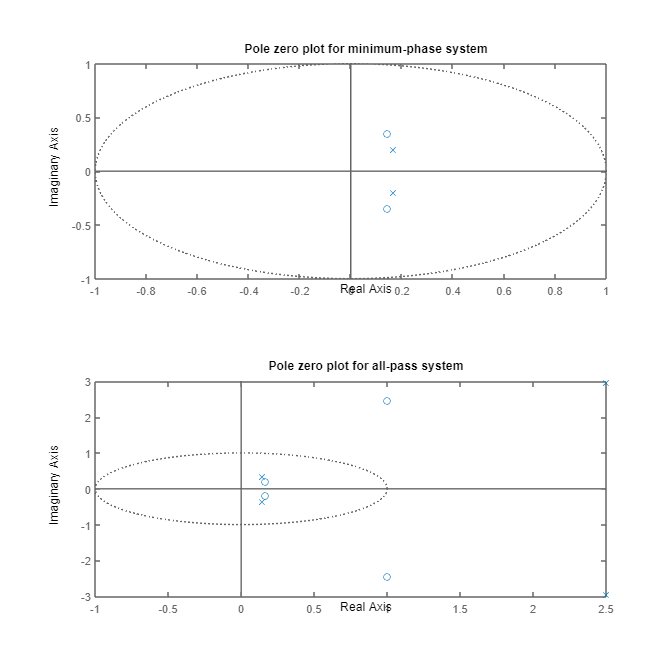

clc; clear; close all;

H_ = tf([1 -2 7], [1 -5 15], -1);

[H_min, H_ap] = get_Fmin_Fapp(H_);

fig1 = figure(Position=[10,10,1000,1000]);
subplot(2,1,1)
pzplot(H_min)
title('Pole zero plot for minimum-phase system')
subplot(2,1,2)
pzplot(H_ap)
title('Pole zero plot for all-pass system')

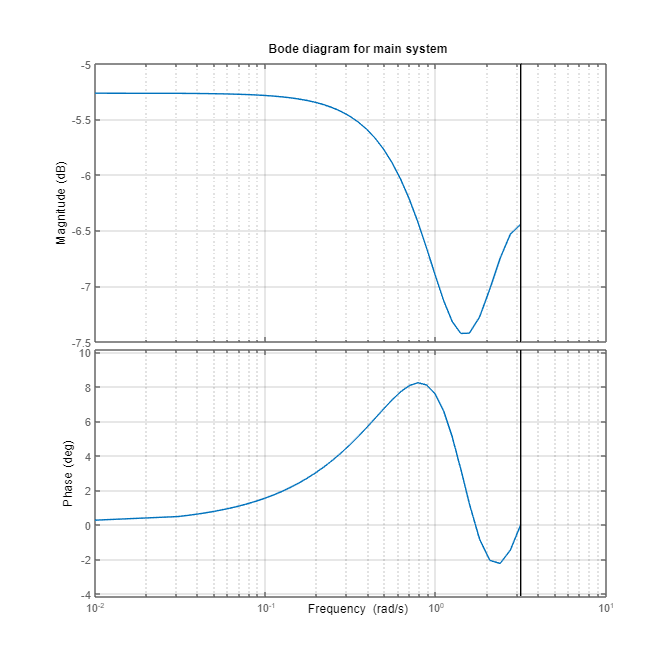

fig2 = figure(Position=[10,10,1000,1000]);
bode(H_);
title('Bode diagram for main system')
grid on

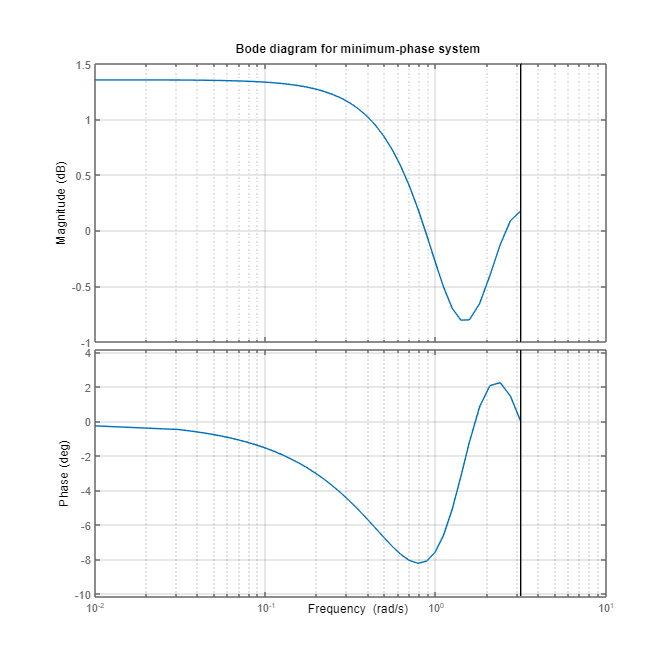


fig3 = figure(Position=[10,10,1000,1000]);
bode(H_min);
title('Bode diagram for minimum-phase system')
grid on

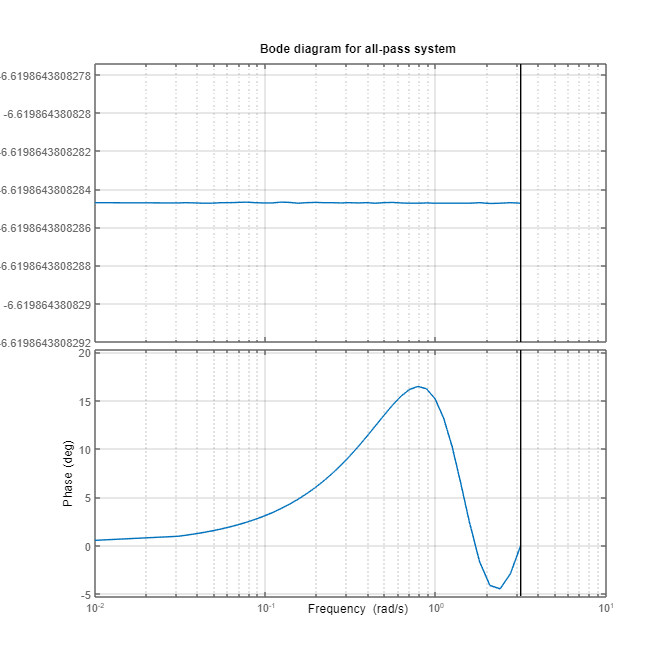


fig4 = figure(Position=[10,10,1000,1000]);
bode(H_ap);
title('Bode diagram for all-pass system')
grid on

***Part 1.2.2:***

No for the second system we have $H\left(z\right)=\frac{\left(z-a\right)\left(z-a^* \right)}{\left(z-b\right)\left(z-b^* \right)}$ where $|a|,|b|>1$, thus: 

$H_{\textrm{ap}} \left(z\right)=\frac{z-a}{1-a^* z}\times \frac{z-a^* }{1-a\;z}\times \frac{1-b^* z}{z-b}\times \frac{1-b\;z}{z-b^* }$ and 

$H_{\min } \left(z\right)=\;$$\frac{1-b^* z}{1-a^* z}\times \frac{1-b\;z}{1-a\;z}$.

clear;
num = [1 -2 7];
den = [1 -5 15];
Ts = 0.01;
H = tf(num, den , Ts)

H =
 
  z^2 - 2 z + 7
  --------------
  z^2 - 5 z + 15
 
Sample time: 0.01 seconds
Discrete-time transfer function.



[F_min, F_ap] = get_Hmin_Happ(num, den, Ts)

F_min =
 
  7 z^4 - 2 z^3 + z^2
  --------------------
  15 z^4 - 5 z^3 + z^2
 
Sample time: 0.01 seconds
Discrete-time transfer function.


F_ap =
 
  15 z^8 - 35 z^7 + 116 z^6 - (37+4.441e-16i) z^5 + 7 z^4
  -------------------------------------------------------
  7 z^8 - (37-4.441e-16i) z^7 + 116 z^6 - 35 z^5 + 15 z^4
 
Sample time: 0.01 seconds
Discrete-time transfer function.



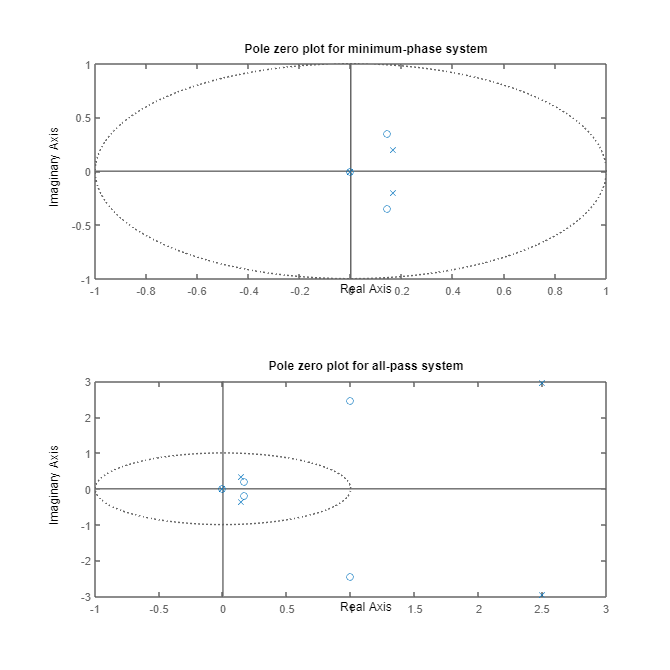

fig1 = figure(Position=[10,10,1000,1000]);
subplot(2,1,1)
pzplot(F_min)
title('Pole zero plot for minimum-phase system')
subplot(2,1,2)
pzplot(F_ap)
title('Pole zero plot for all-pass system')

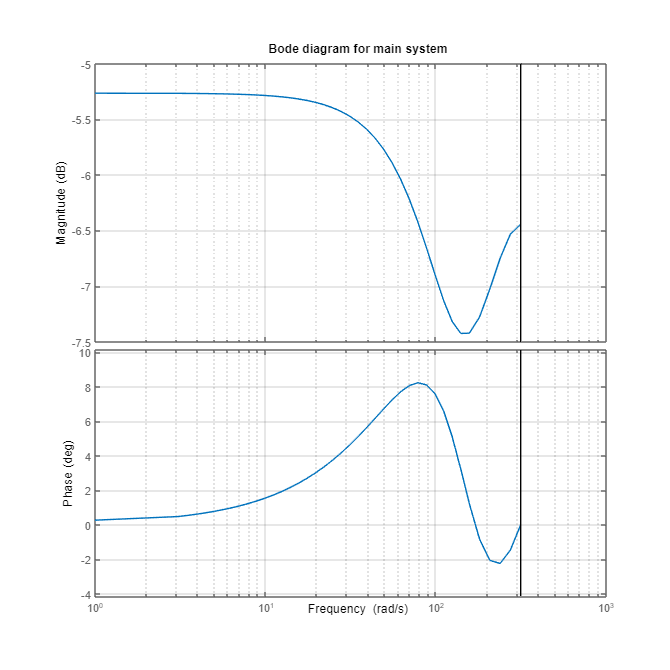

fig2 = figure(Position=[10,10,1000,1000]);
bode(H);
title('Bode diagram for main system')
grid on

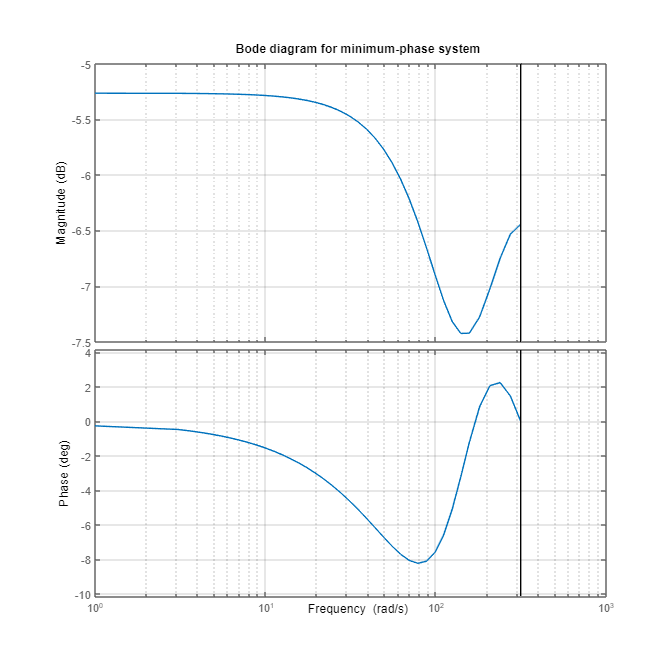


fig3 = figure(Position=[10,10,1000,1000]);
bode(F_min);
title('Bode diagram for minimum-phase system')
grid on

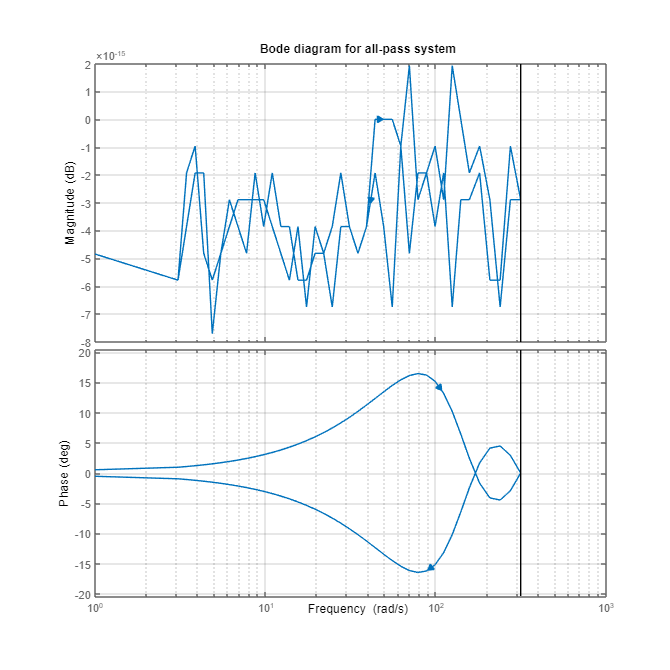


fig4 = figure(Position=[10,10,1000,1000]);
bode(F_ap);
title('Bode diagram for all-pass system')
grid on

It is worth mentioning that we developed annother function in order to get H_mini and H_ap which has the exact same poles and zeros, but it does n't have any problem with pllotting. As you see, there is something wrong with them. But the other method which we applied, confirmed the posistion of our oles and roots, but it was truen on the frequency response of the system.

H_ = tf([1 -2 7], [1 -5 15], -1);

[H_min, H_ap] = get_Fmin_Fapp(H_);
H_min

H_min =
 
  z^2 - 0.2857 z + 0.1429
  ------------------------
  z^2 - 0.3333 z + 0.06667
 
Sample time: unspecified
Discrete-time transfer function.



H_ap

H_ap =
 
  z^4 - 2.333 z^3 + 7.733 z^2 - 2.467 z + 0.4667
  ----------------------------------------------
    z^4 - 5.286 z^3 + 16.57 z^2 - 5 z + 2.143
 
Sample time: unspecified
Discrete-time transfer function.



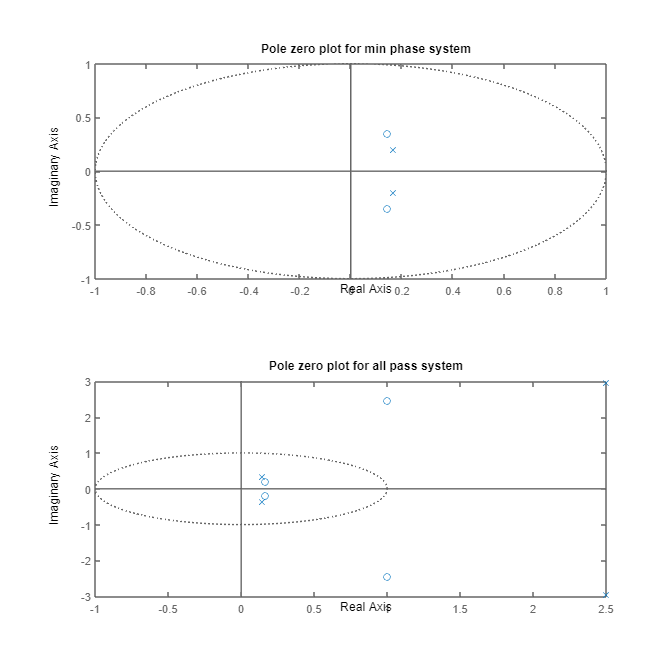

fig1 = figure(Position=[10,10,1000,1000]);
subplot(2,1,1)
pzplot(H_min)
title('Pole zero plot for min phase system')
subplot(2,1,2)
pzplot(H_ap)
title('Pole zero plot for all pass system')


fig2 = figure(Position=[10,10,1000,1000]);
bode(H_);
title('Bode diagram for main system')
grid on


fig3 = figure(Position=[10,10,1000,1000]);
bode(H_min);
title('Bode diagram for minimum-phase system')
grid on

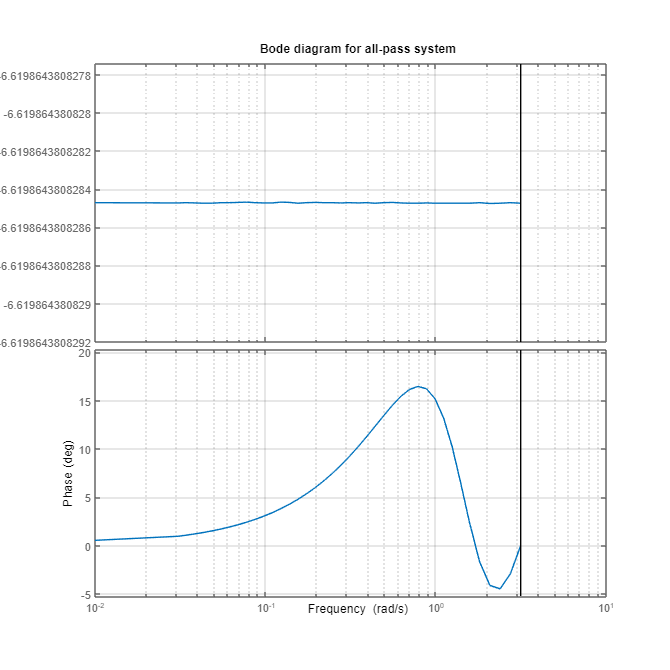


fig4 = figure(Position=[10,10,1000,1000]);
bode(H_ap);
title('Bode diagram for all-pass system')
grid on

Now as you can see, we get what we desired which was decomposing $H(z)$ into two functions that one of them is minimum-phase, while the other one 

***Problem 2:***

***Part 2.1.1, 2,2.1:***

Since $y\left\lbrack n\right\rbrack =x\left\lbrack n-3\right\rbrack$,we can deduce that $H_1 \left(z\right)=z^{-3\;}$. 

 As you can see, the system is all pass since its bode diagram that is depicted shows that it has unity gain.

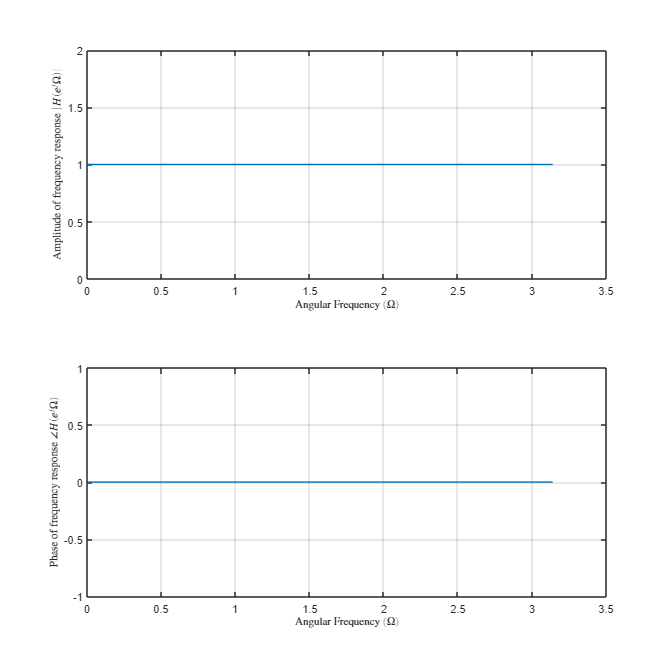

clc; clear; close all;

num = [1];
denom = [1 0 0 0];

[H, w] = freqz(denom, num, 1000);

fig1 = figure(Position=[10,10,1000,1000]);

subplot(2,1,1)
plot(w, abs(H))
xlabel('Angular Frequency $(\Omega)$', Interpreter='latex', FontSize=10);
ylabel('Amplitude of frequency response $|H(e^j\Omega)|$ ', Interpreter='latex', FontSize=10);
grid on

subplot(2,1,2)
plot(w, angle(H))
xlabel('Angular Frequency $(\Omega)$', Interpreter='latex', FontSize=10);
ylabel('Phase of frequency response $ \angle H(e^j\Omega)$', Interpreter='latex', FontSize=10);
grid on

***Part 2.1.2, 2,2.2:***

Since $y\left\lbrack n\right\rbrack -\left(\frac{3}{4}\right)y\left\lbrack n-1\right\rbrack =-\left(\frac{3}{4}\right)x\left\lbrack n\right\rbrack +x\left\lbrack n-1\right\rbrack$,we can deduce that $H_2 \left(z\right)=\frac{-\frac{3}{4}+z^{-1} }{1-\frac{3}{4}z^{-1} }$. 

 As you can see, the system is all pass since its bode diagram that is depicted shows that it has unity gain. 

However, In contrast to the last system, this sytem has nonlinear phase.

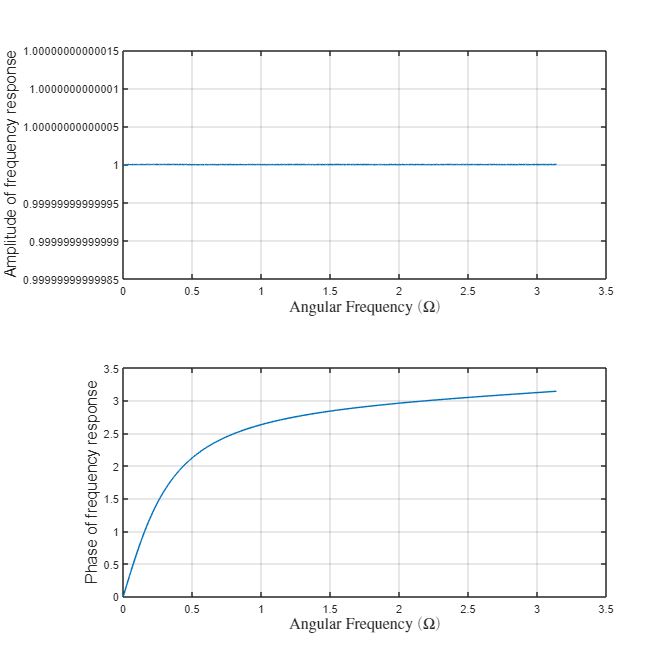

clear; close all; clc;

num = [-3/4 1];
den = [1 -3/4];

[H, w] = freqz(den, num, 1000);

fig1 = figure(Position=[10,10,1000,1000]);

subplot(2,1,1)
plot(w, abs(H))
xlabel('Angular Frequency $(\Omega)$', Interpreter='latex', FontSize=14);
ylabel('Amplitude of frequency response', FontSize=14);
grid on

subplot(2,1,2)
plot(w, angle(H))
xlabel('Angular Frequency $(\Omega)$', Interpreter='latex', FontSize=14);
ylabel('Phase of frequency response', FontSize=14);
grid on

***Part 2.3:***

Now we let $Y_1, Y_2$ to be the outputs of $x[n] = (3/4)^n u[n]$ to the systems $H_1, H_2$, respectively.

Since we are getting 50-point FFt of Y1 and Y2, the base harmonic frequency will be $\Omega = \frac{2\pi}{50}$ .

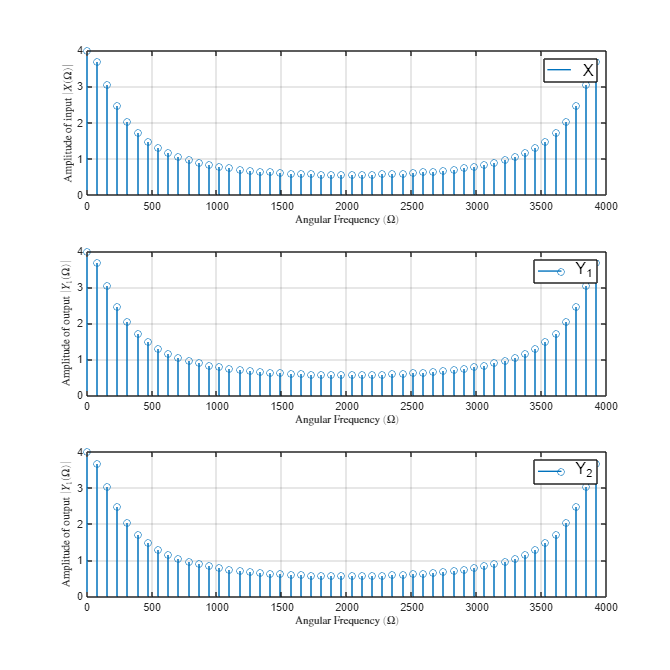

clc; clear; close all;
% defining the n and the input and the base frequency harmonic
omega = (0:50)/2*pi*50;
n = 0:50;
x = (0.75).^n;
% defining the systems\ transfer functions
H1_z = tf([1], [1 0 0 0], -1);
H2_z = tf([-3/4 1], [1 -3/4], -1);
% getting the output to the systems with input x
y1_n = lsim(H1_z, x, n);
y2_n = lsim(H2_z, x, n);
% getting fft from inputs and outputs
X = fft(x);
Y1_z = fft(y1_n);
Y2_z = fft(y2_n);

% plotting the result
fig = figure(Position=[10 10 1000 1000]);

subplot(3,1,1);
stem(omega,abs(X));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of input $|X(\Omega)|$', FontSize=10, Interpreter='latex');
legend('X', FontSize=14);
grid on

subplot(3,1,2);
stem(omega,abs(Y1_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of output $|Y_1(\Omega)|$', FontSize=10, Interpreter='latex');
legend('Y_1', FontSize=14);
grid on

subplot(3,1,3);
stem(omega,abs(Y2_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of output $|Y_1(\Omega)|$', FontSize=10, Interpreter='latex');
legend('Y_2', FontSize=14);
grid on

As you can see, Since the input goes through an all pass system, the magnitude of the output will be identical to the magnitude of the input.

***Part 2.4, 2,5, 2.6:***

Firsltly, we will calculate $y_{in} , 1\leq i \leq 2 ; 1 \leq n \leq 4$ and plot them in time domain, then, we will plot their fft's in frequency domain

% output through system 1
y11_n = lsim(H1_z, x, n);
y12_n = lsim(H1_z, y1_n, n);
y13_n = lsim(H1_z, y1_n, n);
y14_n = lsim(H1_z, y1_n, n);
% output through system 2
y21_n = lsim(H2_z, x, n);
y22_n = lsim(H2_z, y2_n, n);
y23_n = lsim(H2_z, y2_n, n);
y24_n = lsim(H2_z, y2_n, n);
% fft of outputs of system 1
Y11_z = fft(y11_n);
Y12_z = fft(y12_n);
Y13_z = fft(y13_n);
Y14_z = fft(y14_n);
% fft of outputs of system 1
Y21_z = fft(y21_n);
Y22_z = fft(y22_n);
Y23_z = fft(y23_n);
Y24_z = fft(y24_n);
% calculating the phase 


The $y_{12}[n],..,y_{124}[n]$ are depicted down below:

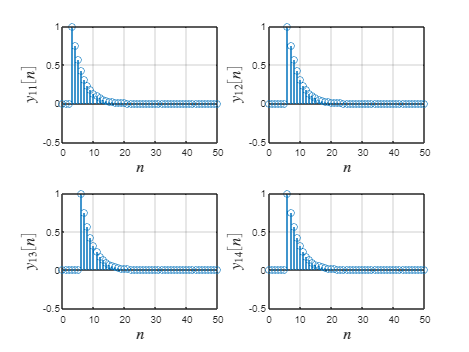

figure;
% plottings
subplot(2,2,1);
stem(n,y11_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{11}[n]$', FontSize=14, Interpreter='latex');
ylim([-.5 1]);
xlim([0 50]);
grid on

subplot(2,2,2);
stem(n,y12_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{12}[n]$', FontSize=14, Interpreter='latex');
ylim([-.5 1]);
xlim([0 50]);
grid on

subplot(2,2,3);
stem(n,y13_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{13}[n]$', FontSize=14, Interpreter='latex');
ylim([-.5 1]);
xlim([0 50]);
grid on

subplot(2,2,4);
stem(n,y14_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{14}[n]$', FontSize=14, Interpreter='latex');
ylim([-.5 1]);
xlim([0 50]);
grid on

The $y_{21}[n],..,y_{24}[n]$ are depicted down below:

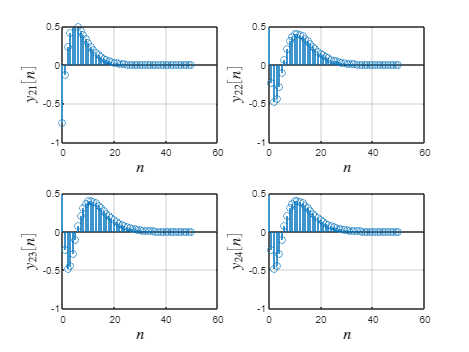

figure;
% plottings
subplot(2,2,1);
stem(n,y21_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{21}[n]$', FontSize=14, Interpreter='latex');
ylim([-1 .5]);
grid on

subplot(2,2,2);
stem(n,y22_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{22}[n]$', FontSize=14, Interpreter='latex');
ylim([-1 .5]);
grid on

subplot(2,2,3);
stem(n,y23_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{23}[n]$', FontSize=14, Interpreter='latex');
ylim([-1 .5]);
grid on

subplot(2,2,4);
stem(n,y24_n);
xlabel('$n$', FontSize=14, Interpreter='latex');
ylabel('$y_{24}[n]$', FontSize=14, Interpreter='latex');
ylim([-1 .5]);
grid on

Here are the amplitudes of $Y_{11}, ... , Y_{14}$'s ffts:

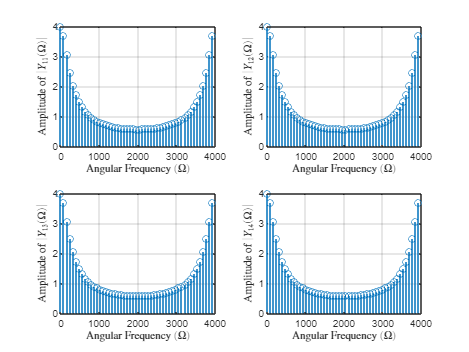

figure;
subplot(2,2,1);
stem(omega,abs(Y11_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{11}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,2);
stem(omega,abs(Y12_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{12}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,3);
stem(omega,abs(Y13_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{13}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,4);
stem(omega,abs(Y14_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{14}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

As you can see, the amplitudes are still identical to the magnitude of input's fft, since no matter how many times we let the signal pass through cacaded all pass filters, 

the outputs's magnitude remains  the same. As in the next plot this point of view is obvious as well.

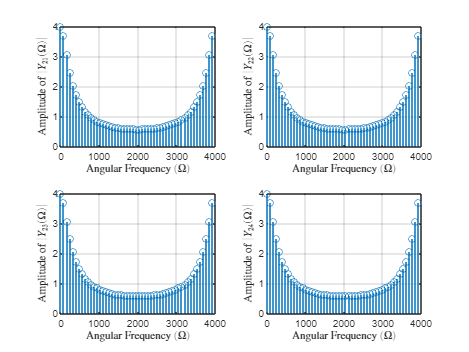

figure;
subplot(2,2,1);
stem(omega,abs(Y21_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{21}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,2);
stem(omega,abs(Y22_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{22}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,3);
stem(omega,abs(Y23_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{23}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,4);
stem(omega,abs(Y24_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Amplitude of $|Y_{24}(\Omega)|$', FontSize=10, Interpreter='latex');
grid on

The phase of inputs passing through the first channel is depicted down here. As you can see, the phase is linear. This is due to the fact that 

our system was only shifting the input in one direction.

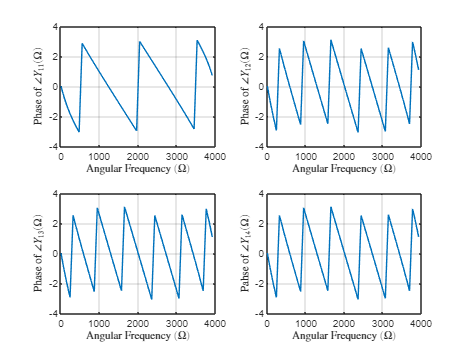

figure;
subplot(2,2,1);
plot(omega,angle(Y11_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Phase of $\angle Y_{11}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,2);
plot(omega,angle(Y12_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Phase of $ \angle Y_{12}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,3);
plot(omega,angle(Y13_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Phase of $ \angle Y_{13}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,4);
plot(omega,angle(Y14_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Pahse of $ \angle Y_{14}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

The phase of inputs passing through the second channel is depicted down here. As you can see, the phase is nonlinear. This is due to the fact that 

In contrast to the first system that was only shifting the input in one direction, our system is more comlicated and is describedd by a difference equation 

that has shifted versions of input and output.

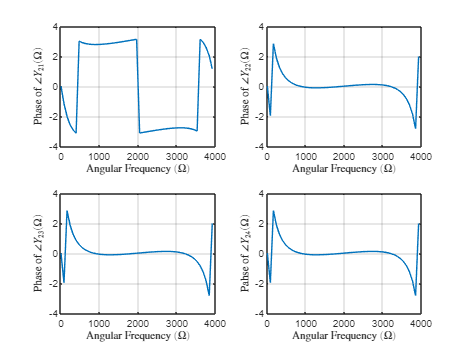

figure;
subplot(2,2,1);
plot(omega,angle(Y21_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Phase of $\angle Y_{21}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,2);
plot(omega,angle(Y22_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Phase of $ \angle Y_{22}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,3);
plot(omega,angle(Y23_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Phase of $ \angle Y_{23}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

subplot(2,2,4);
plot(omega,angle(Y24_z));
xlabel('Angular Frequency $(\Omega)$', FontSize=10, Interpreter='latex');
ylabel('Pahse of $ \angle Y_{24}(\Omega)$', FontSize=10, Interpreter='latex');
grid on

***Part 2.7:***

We will show that if an energy-type signal $x[n]$ pass through a all pass filter with impulse response $h[n]$, its energy will be the same.

Let the output be named $y[n]$. We know that the spectral density of y is :

$S_y \left(\Omega \;\right)=|H\left(e^{j|\Omega \;} \right)|^2 \;S_x \left(\Omega \;\right)$and since the frequency response of $h[n]$ is always1, we obtain: $S_y \left(\Omega \;\right)=\;S_x \left(\Omega \;\right)$

, and hence they have the same spectral density and energy.

$E\left(|{y\left(n\right)|}^2 \right)=\frac{1}{2\pi \;}\int_0^{2\pi \;} S_y \left(\Omega \;\right)d\Omega \;=\frac{1}{2\pi \;}\int_0^{2\pi \;} S_x \left(\Omega \;\right)d\Omega \;=E\left({|x\left(n\right)|}^2 \right)\;$.

E_x = sum(abs(x.^2))

E_x = 2.2857

E_y21_n = sum(abs(y21_n.^2))

E_y21_n = 2.2857

E_y22_n = sum(abs(y22_n.^2))

E_y21_n = 2.2857

E_y23_n = sum(abs(y23_n.^2))

E_y23_n = 2.2857

E_y24_n = sum(abs(y24_n.^2))

E_y24_n = 2.2857

***Part 3.1:***

***Butterworth ***needs 23 poles as well as one zero.

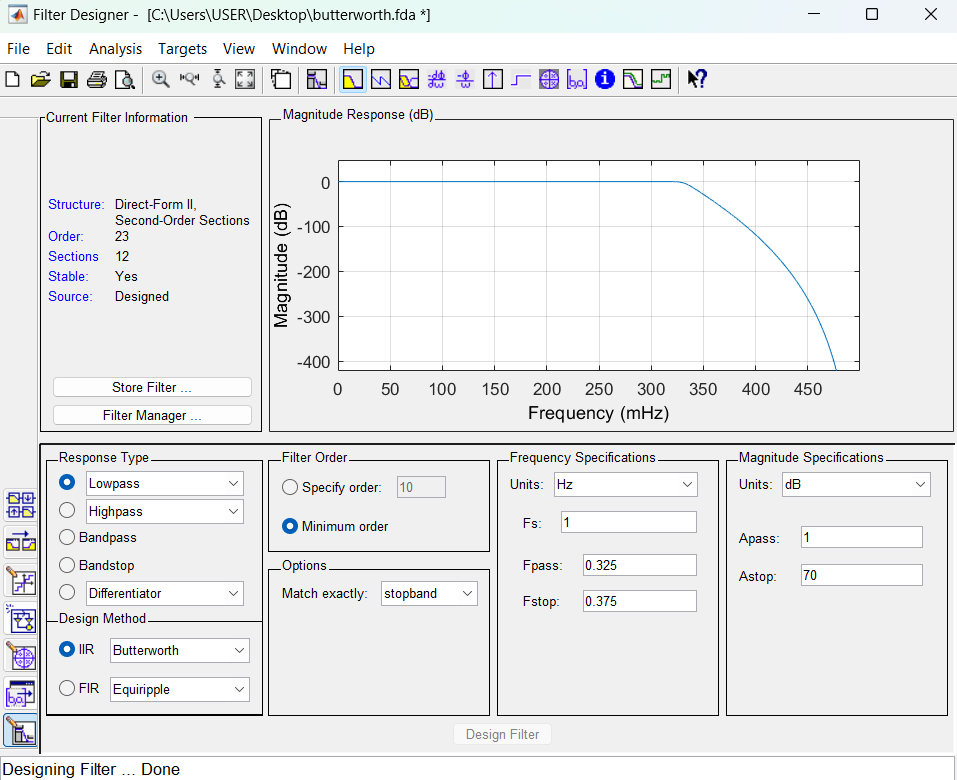

% and as you can see, the poles and zeros are depicted down here:

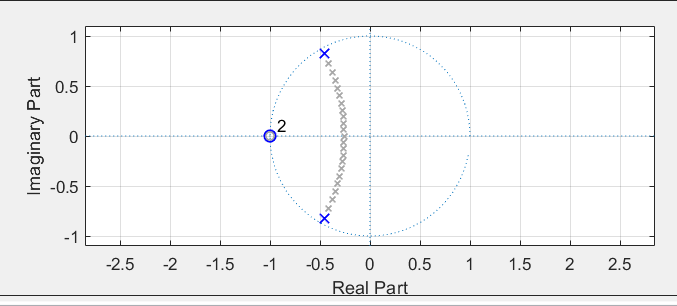

***Part 3.2:***

***Chebyshev I: ***needs 10 poles as well as one zero.

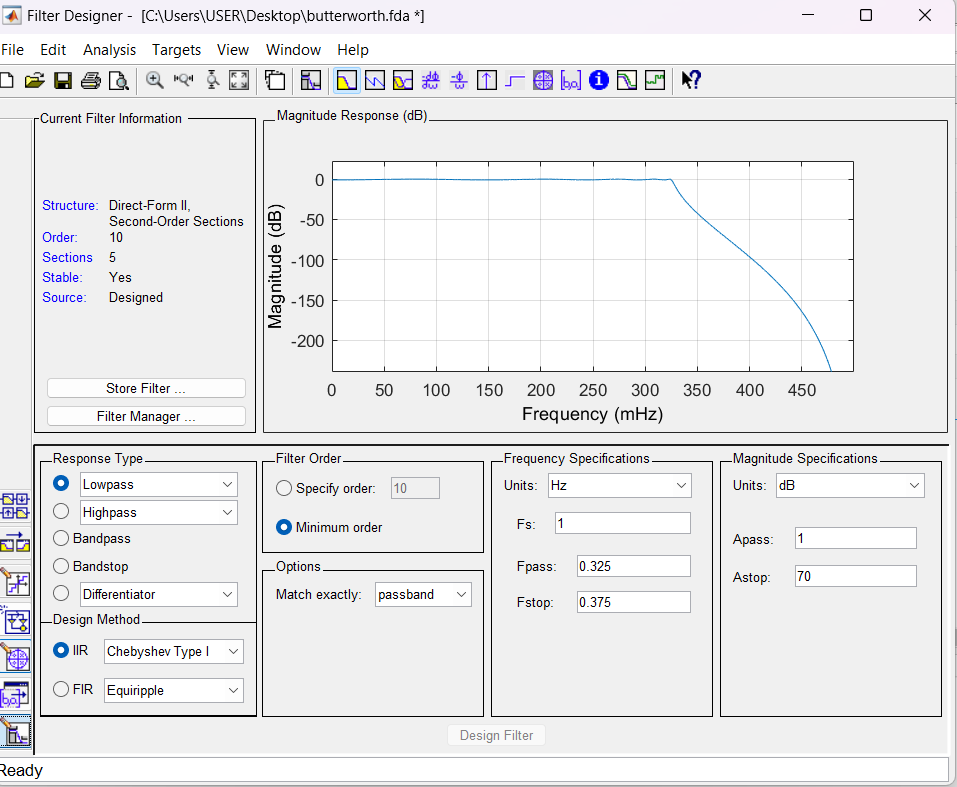

% and as you can see, the poles and zeros are depicted down here:

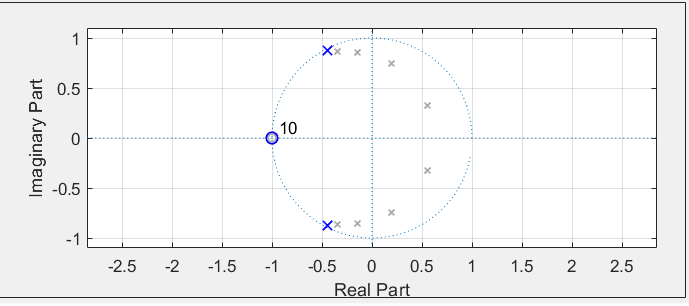

***Part 3.3: Chebyshev II: ***needs 10 poles as well as 10 zeros.

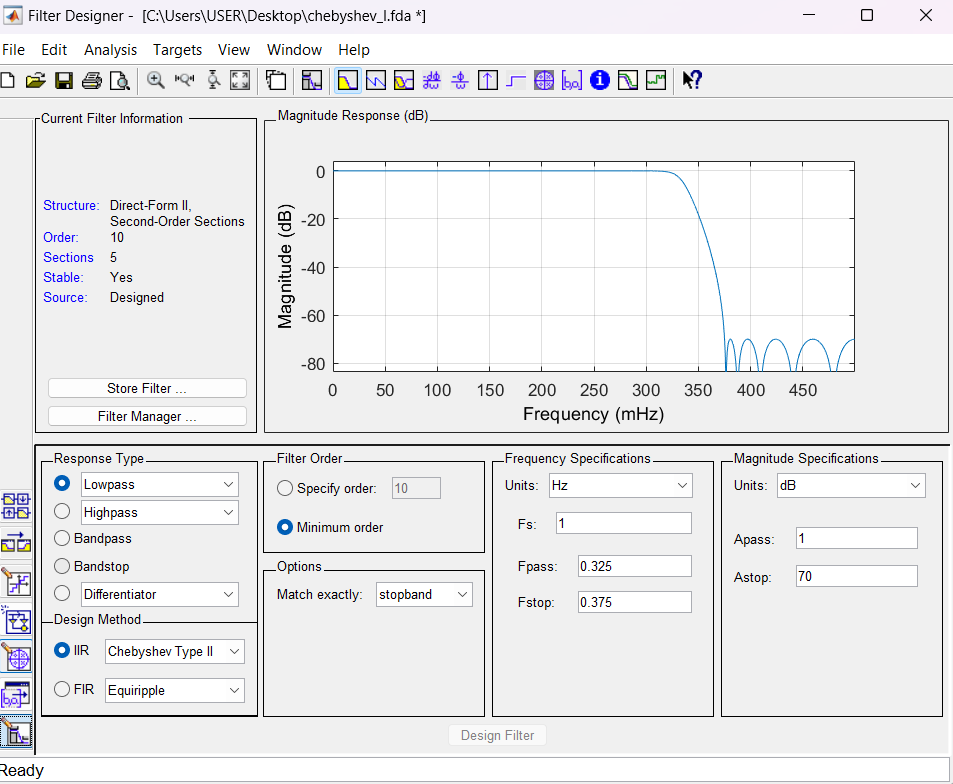

% and as you can see, the poles and zeros are depicted down here:

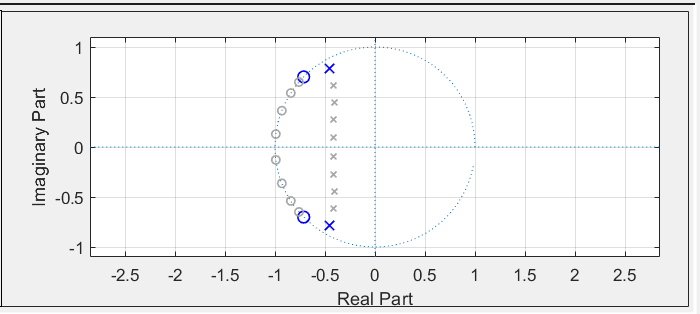

***Part 3.4: Eliiptic: ***needs 10 poles as well as 10 zeros.

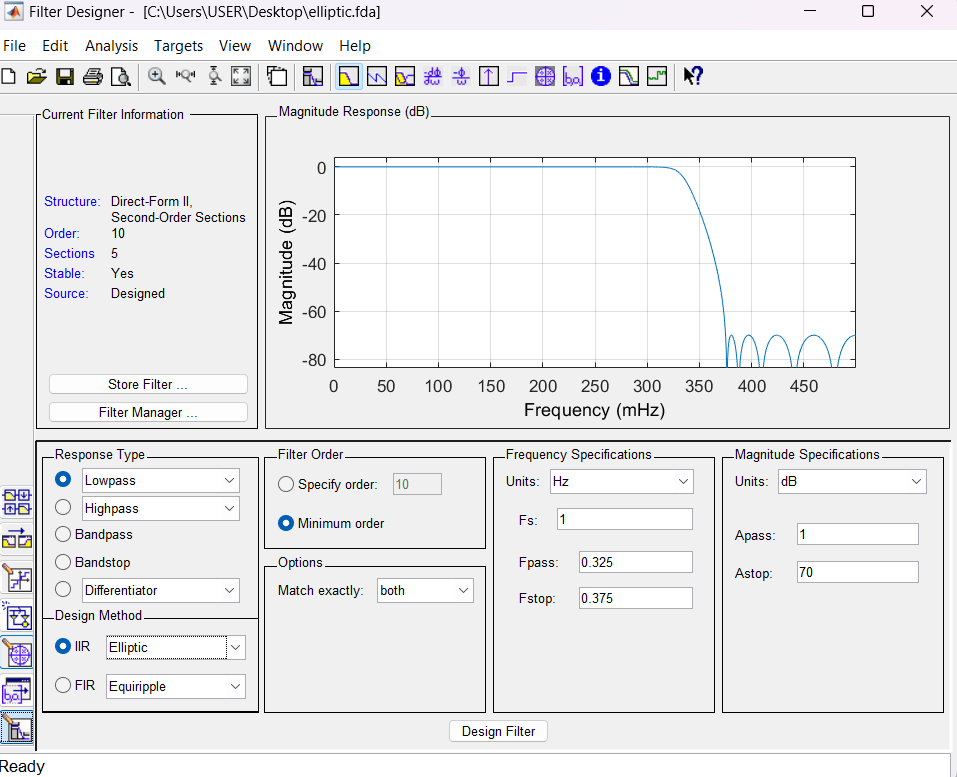

% and as you can see, the poles and zeros are depicted down here:

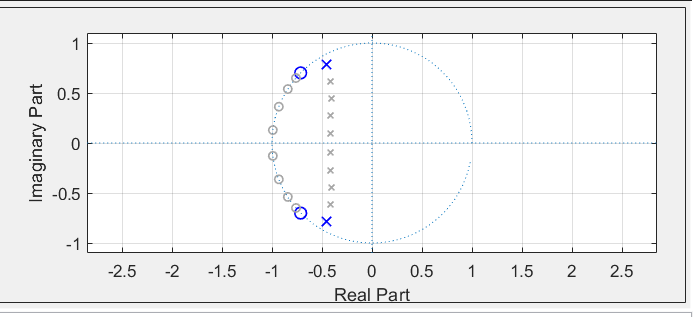

function [a_hat, b_hat] = remove_redundancy(a,b)
a = transpose(a);
b = transpose(b);
for x =a
    if ismember(x,b)
        indices_b = find(b == x);
        indices_a = find(a == x);
        b(indices_b(1)) = [];
        a(indices_a(1)) = [];
    end
end
a_hat = transpose(a);
b_hat = transpose(b);
end
% ----------------------------------------------------------
function [lt1, get1] = separator(list)
lt1 = [];
get1 = [];
if ~isempty(list)
for x = list
    if abs(x)<1
        lt1(end+1) = x;
    else
        get1(end+1) = x;
    end
end
end
end
% ----------------------------------------------------------
function [H_min, H_ap] = get_Hmin_Hap(num, den, Ts)
z = tf('z', Ts);
H_tf = tf(num, den, Ts);
H_min = tf([1],[1], Ts);
H_ap = tf([1],[1], Ts);
zeros_tf = zero(H_tf);
poles_tf = zero(1/H_tf);
[zeros, poles] = remove_redundancy(zeros_tf,poles_tf);
[poles_lt1, poles_get1] = separator(transpose(poles));
[roots_lt1, roots_get1] = separator(transpose(zeros));
for p = poles_lt1
H_min = H_min / (z - p);
end
for r = roots_lt1
H_min = H_min * (z - r);
end
for p = poles_get1
H_ap = H_ap / (z-p); 
H_ap = H_ap * (1-conj(p)*z);
H_min = H_min / (1-conj(p)*z);
end
for r = roots_get1
H_ap = H_ap * (z - r);
H_ap = H_ap / (1-conj(r)*z);
H_min = H_min * (1-conj(r)*z);
end
end
% ----------------------------------------------------------
function [H_min, H_ap] = get_Hmin_Happ(num, den, Ts)
z = tf('z', Ts);
H_tf = tf(num, den, Ts);
H_min = tf([1],[1], Ts);
H_ap = tf([1],[1], Ts);
zeros_tf = zero(H_tf);
poles_tf = zero(1/H_tf);
[zeros, poles] = remove_redundancy(zeros_tf,poles_tf);
[poles_lt1, poles_get1] = separator(transpose(poles));
[roots_lt1, roots_get1] = separator(transpose(zeros));
for p = poles_lt1
H_min = H_min / (1 - p*(z^-1));
end
for r = roots_lt1
H_min = H_min * (1 - r*(z^-1));
end
for p = poles_get1
H_ap = H_ap / (1 - p*(z^-1));
H_ap = H_ap * ((z^-1) - conj(p));
H_min = H_min /((z^-1) - conj(p));

end
for r = roots_get1
H_ap = H_ap * (1 - r*(z^-1));
H_ap = H_ap / ((z^-1) - conj(r));
H_min = H_min * ((z^-1) - conj(r));
end
end
% ----------------------------------------------------------
function [H_min, H_ap] = get_Fmin_Fapp(Hsys)
    num = cell2mat(Hsys.Numerator);
    denom = cell2mat(Hsys.Denominator);
    zeros_H = roots(num);
    poles_H = roots(denom);
    zeros_Hmin = cat(1, zeros_H(abs(zeros_H) < 1), 1./conj(zeros_H(abs(zeros_H) > 1)));
    poles_Hmin = cat(1, poles_H(abs(poles_H) < 1), 1./conj(poles_H(abs(poles_H) > 1)));
    zeros_Hap = cat(1, zeros_H(abs(zeros_H) > 1), 1./conj(poles_H(abs(poles_H) > 1)));
    poles_Hap = cat(1, poles_H(abs(poles_H) > 1), 1./conj(zeros_H(abs(zeros_H) > 1)));
    Hmin_num = poly(zeros_Hmin);
    Hmin_denom = poly(poles_Hmin);
    Hap_num = poly(zeros_Hap);
    Hap_denom = poly(poles_Hap);
    H_min = tf(Hmin_num, Hmin_denom, -1);
    H_ap = tf(Hap_num, Hap_denom, -1);
end